# Using Clustering to Segment Images

This file contains the code you saw in the *Using Clustering To Segment Images* video and is provided for your reference.

Read in the colored chips image:

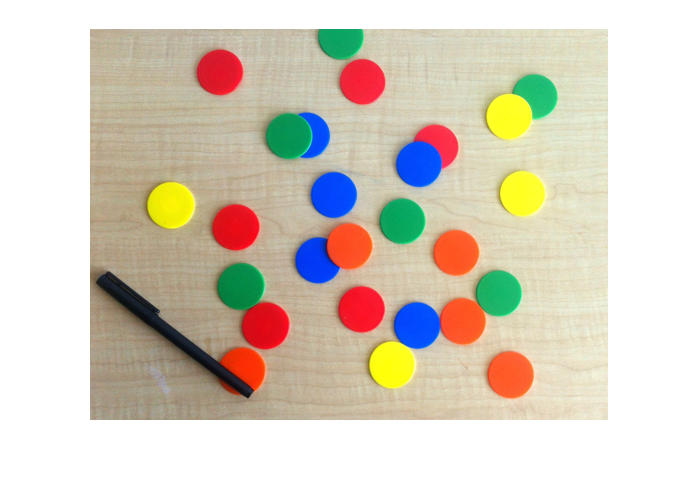

RGB = imread("coloredChips.png"); 
imshow(RGB)

Try clustering in the HSV color space with 7 clusters: 

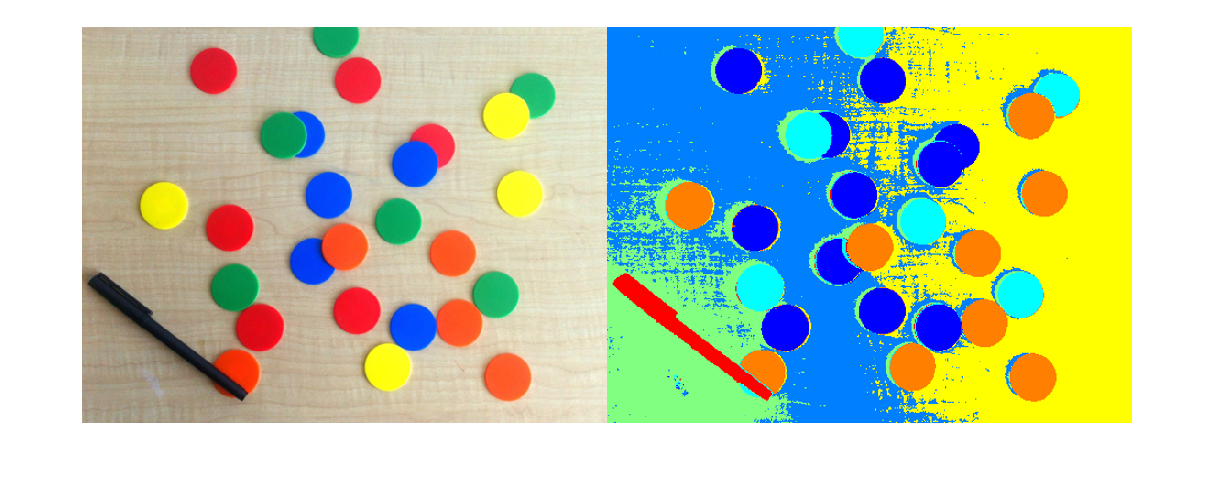

HSV = rgb2hsv(RGB); 
K = 7; 
labels = imsegkmeans(im2single(HSV),K);
montage({RGB,label2rgb(labels)})

Remove the table by thresholding the Saturation and check the results: 

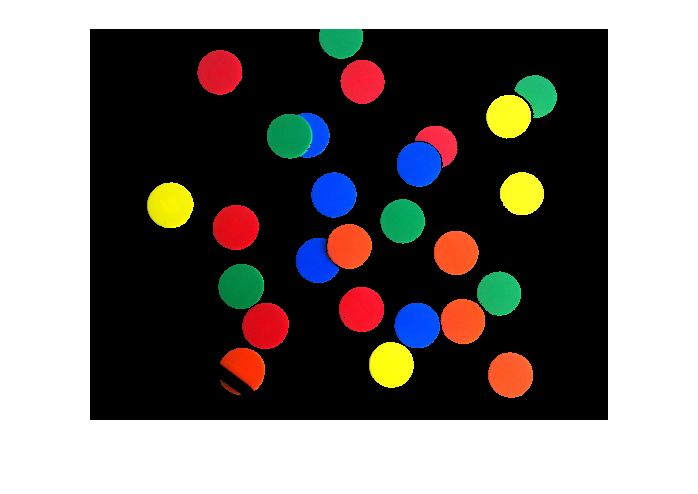

chipmask = HSV(:,:,2) > 0.75; 
HSVchip = HSV; 
HSVchip(~repmat(chipmask,1,1,3)) = 0; 
imshow(hsv2rgb(HSVchip))

Cluster the resulting image using 6 clusters: 

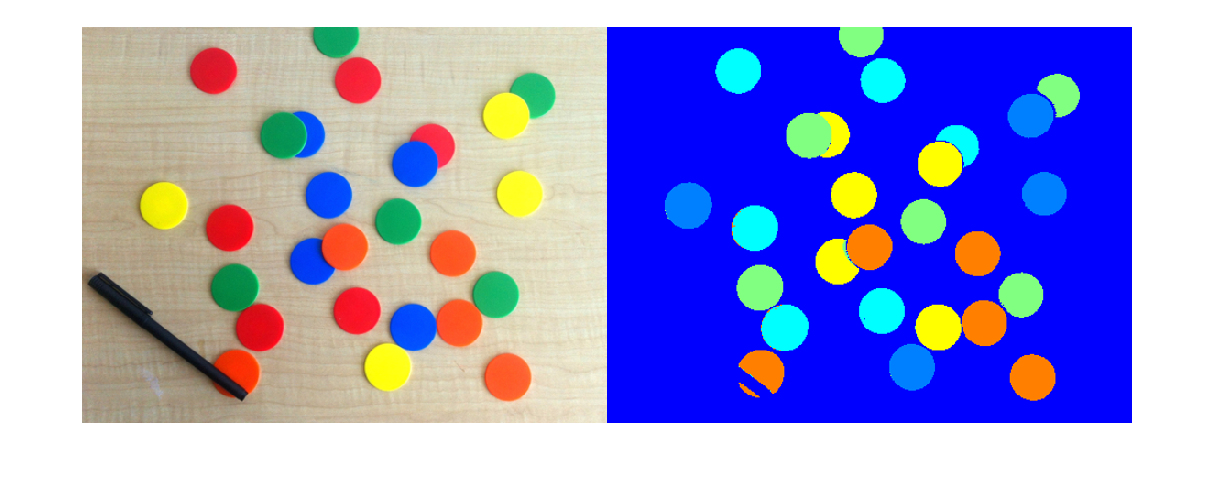

K = 6; 
labels = imsegkmeans(im2single(HSVchip),K);
montage({RGB,label2rgb(labels)})

*Copyright 2022 The MathWorks, Inc.*